# Assignment: Hurricane Harvey Report

## Background and Scope

### Import the file StormEvents_2017_finalProject.csv

%This section was automatically generated using import tool
%To import your own data change the filepath in line 26
opts = delimitedTextImportOptions("NumVariables", 24);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["EpisodeID", "Event_ID", "State", "Year", "Month", "Event_Type", "CZ_Name", "Begin_Date_Time", "Timezone", "End_Date_Time", "Injuries_Direct", "Injuries_Indirect", "Deaths_Direct", "Deaths_Indirect", "Damage_Property", "Property_Cost", "Damage_Crops", "Crop_Cost", "Begin_Lat", "Begin_Lon", "End_Lat", "End_Lon", "Episode_Narrative", "Event_Narrative"];
opts.VariableTypes = ["double", "double", "categorical", "double", "categorical", "categorical", "categorical", "datetime", "double", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Event_Narrative", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["State", "Month", "Event_Type", "CZ_Name", "Episode_Narrative", "Event_Narrative"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Begin_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "End_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "ThousandsSeparator", ",");

% Import the data and write your own filepath inside readtable function
StormEvents2017finalProject = readtable("F:\Competitions\Coursera\Matlab\Exploratory Data Analysis\StormEvents\StormEvents\StormEvents_2017_finalProject.csv", opts);



clear opts



### Two States Most Impacted by Harvey

The two states most affected by Hurricane Harvey were Texas and Louisiana

StormEvents2017finalProject_Harvey = StormEvents2017finalProject(ismember(StormEvents2017finalProject.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);
StormEvents2017finalProject_Harvey = StormEvents2017finalProject_Harvey(ismember(StormEvents2017finalProject_Harvey.Month,{'August','September'}),:);
StormEvents2017finalProject_Harvey = sortrows(StormEvents2017finalProject_Harvey,'Begin_Date_Time');
StormEvents2017finalProject_Harvey = StormEvents2017finalProject_Harvey(228:805,:); 
%I tried to select events ranging from 17.08.2017-03.09.2017 from live script, but the selection would not hold. That is why selected the rows manually.
StormEvents2017finalProject_Harvey = StormEvents2017finalProject_Harvey(~ismissing(StormEvents2017finalProject_Harvey.Property_Cost),:);
%head(StormEvents2017finalProject_Harvey)
%Uncomment to see a preview of 2017 storm events

PropertyCostbyState = groupsummary(StormEvents2017finalProject_Harvey,"State",'sum','Property_Cost');

PropertyCostbyState = PropertyCostbyState(~ismissing(PropertyCostbyState.sum_Property_Cost),:);
PropertyCostbyState = sortrows(PropertyCostbyState,'sum_Property_Cost','descend')

PropertyCostbyState = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                273           7.7427e+10    
    LOUISIANA             86           7.5277e+07    
    NORTH CAROLINA        54           1.2339e+07    
    MISSISSIPPI           39             9.15e+05    
    TENNESSEE             46             5.04e+05    
    KENTUCKY              16             4.35e+05    
    ARKANSAS              53                61000    


### Table of Events for Two Most Impacted States

TwoMostAffectedStates = StormEvents2017finalProject_Harvey(ismember(StormEvents2017finalProject_Harvey.State,{'LOUISIANA','TEXAS'}),:);

TwoMostAffectedStates.Event_Type = removecats(TwoMostAffectedStates.Event_Type,{'Astronomical Low Tide','Avalanche','Blizzard','Coastal Flood','Cold/Wind Chill','Debris Flow','Dense Fog','Dense Smoke','Drought','Dust Devil','Dust Storm','Excessive Heat','Extreme Cold/Wind Chill'});
TwoMostAffectedStates.Event_Type = removecats(TwoMostAffectedStates.Event_Type,{'Funnel Cloud','Hail','Heavy Rain','Freezing Fog','Frost/Freeze','Heavy Snow','High Surf','High Wind','Ice Storm','Lake-Effect Snow','Lakeshore Flood','Lightning','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Rip Current','Sleet','Sneakerwave','Strong Wind','Tropical Depression','Waterspout','Wildfire','Winter Storm','Winter Weather'});
%A preview of the table containing events for two most affected states
head(TwoMostAffectedStates)

ans = 8×24 table
    EpisodeID      Event_ID     State    Year    Month     Event_Type     CZ_Name      Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                   Episode_Narrative                                                                                                                    

## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

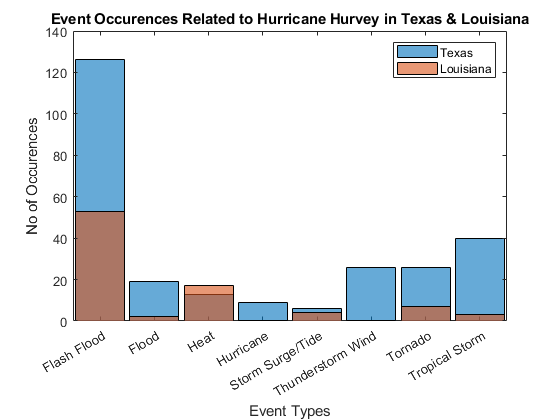

Texas = TwoMostAffectedStates(TwoMostAffectedStates.State == 'TEXAS',:);
Louisiana = TwoMostAffectedStates(TwoMostAffectedStates.State == 'LOUISIANA',:);
histogram(Texas.Event_Type)
hold on
histogram(Louisiana.Event_Type)
hold off

title('Event Occurences Related to Hurricane Hurvey in Texas & Louisiana')
xlabel('Event Types')
ylabel('No of Occurences')

legend('show', 'Texas', 'Louisiana')

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

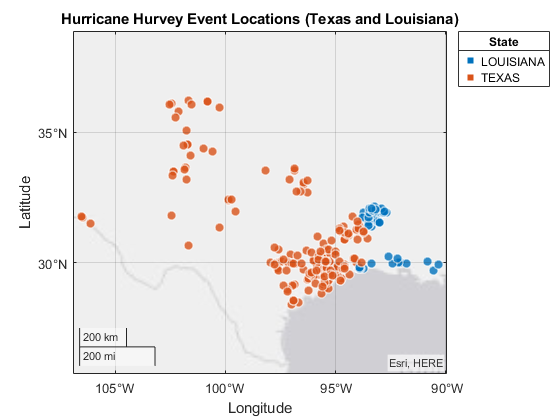

TwoMostAffectedStates;

TwoMostAffectedStates.State = removecats(TwoMostAffectedStates.State,{'ALABAMA','ALASKA','AMERICAN SAMOA','ARIZONA','ARKANSAS','ATLANTIC NORTH','ATLANTIC SOUTH','CALIFORNIA','COLORADO','CONNECTICUT','DELAWARE','DISTRICT OF COLUMBIA','E PACIFIC','FLORIDA','GEORGIA','GUAM','GULF OF MEXICO','HAWAII','HAWAII WATERS','IDAHO','ILLINOIS','INDIANA','IOWA','KANSAS','KENTUCKY','LAKE ERIE','LAKE HURON','LAKE MICHIGAN','LAKE ONTARIO','LAKE ST CLAIR','LAKE SUPERIOR','MAINE','MARYLAND','MASSACHUSETTS','MICHIGAN','MINNESOTA','MISSISSIPPI','MISSOURI','MONTANA','NEBRASKA','NEVADA','NEW HAMPSHIRE','NEW JERSEY','NEW MEXICO','NEW YORK','NORTH CAROLINA','NORTH DAKOTA','OHIO','OKLAHOMA','OREGON','PENNSYLVANIA','PUERTO RICO','RHODE ISLAND','SOUTH CAROLINA','SOUTH DAKOTA','ST LAWRENCE R','TENNESSEE','UTAH','VERMONT','VIRGIN ISLANDS','VIRGINIA','WASHINGTON','WISCONSIN','WYOMING','WEST VIRGINIA'});
geobubble(TwoMostAffectedStates, "Begin_Lat","Begin_Lon", "ColorVariable","State")

legend show
title('Hurricane Hurvey Event Locations (Texas and Louisiana)')

## Analysis

### Three Counties with Most Events in State 1-Texas

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

MostEventsCountiesTexas = groupsummary(Texas,"CZ_Name" , 'sum', 'Property_Cost');

MostEventsCountiesTexas = sortrows(MostEventsCountiesTexas,'GroupCount','descend');
MostEventsCountiesTexas = MostEventsCountiesTexas(1:3,:)

MostEventsCountiesTexas = 3×3 table
     CZ_Name     GroupCount    sum_Property_Cost
    _________    __________    _________________

    HARRIS           21           1.0001e+10    
    GALVESTON        17                2e+10    
    FORT BEND        13           1.6004e+10    


Top three counties with most events in Texas are Harris, Galvestion and Fort Bend

### Three Counties with Most Events in State 2- Louisiana

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

MostEventsCountiesLouisiana = groupsummary(Louisiana,"CZ_Name",'sum', 'Property_Cost');

MostEventsCountiesLouisiana = sortrows(MostEventsCountiesLouisiana,'GroupCount','descend');
MostEventsCountiesLouisiana = MostEventsCountiesLouisiana(1:3,:)

MostEventsCountiesLouisiana = 3×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    NATCHITOCHES        21                0        
    SABINE              15                0        
    RED RIVER            9                0        


Top three counties with most events in Louisiana are Natchitoches, Sabine and Red River.

### Three Counties with Highest Property Cost in State 1- Texas

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 1. *Be sure to include the dollar amount*. 

MostPropCosCountiesTexas = groupsummary(Texas,"CZ_Name", 'sum', 'Property_Cost');

MostPropCosCountiesTexas = sortrows(MostPropCosCountiesTexas,'sum_Property_Cost','descend');
MostPropCosCountiesTexas = MostPropCosCountiesTexas(1:3,:)

MostPropCosCountiesTexas = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17                2e+10    
    FORT BEND         13           1.6004e+10    
    MONTGOMERY         6              1.4e+10    


### Three Counties with Highest Property Cost in State 2 - Louisiana

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 2. *Be sure to include the dollar amount*. 

MostPropCosCountiesLouisiana = groupsummary(Louisiana,"CZ_Name", 'sum', 'Property_Cost');

MostPropCosCountiesLouisiana = sortrows(MostPropCosCountiesLouisiana,'sum_Property_Cost','descend');
MostPropCosCountiesLouisiana = MostPropCosCountiesLouisiana(1:3,:)

MostPropCosCountiesLouisiana = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1                6e+07     
    BEAUREGARD        1              1.5e+07     
    ACADIA            1                2e+05     


## Conclusions and Recommendations

The insurance company should send people to places with  high number of Events and high Property Damage Cost.

Texas

- Galveston

- Fort Bend

- Montgomery

Louisiana

- Calcasieu

- Beauregard

- Acadia